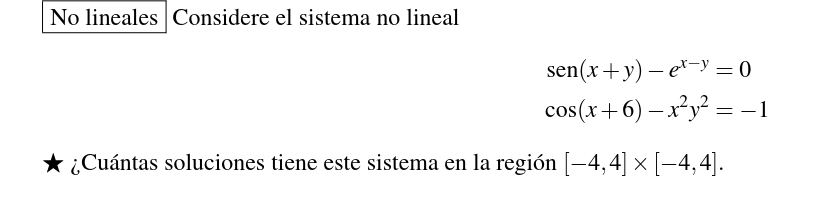

clear;
syms f(x,y) g(x,y)

figure;

f(x, y) = sin(x + y) - exp(x - y)

$$f(x, y) = \sin\left(x+y\right)-{\mathrm{e}}^{x-y}$$

% Graficar la primera función usando fimplicit
fimplicit(f(x,y), [-4 4 -4 4])

hold on
g(x,y)= cos(x + 6) - x^2*y^2 + 1

$$g(x, y) = \cos\left(x+6\right)-x^{2}\,y^{2}+1$$

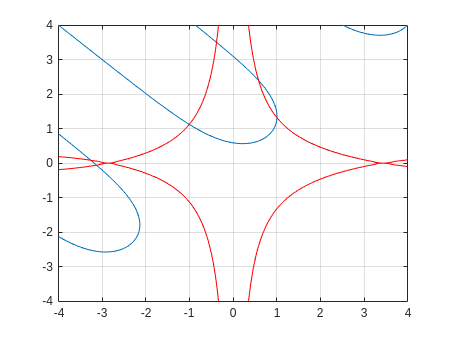

% Graficar la segunda función usando fimplicit y color rojo
fimplicit(g(x,y), [-4 4 -4 4], 'r')
    
grid on



F = @(P) [sin(P(1) + P(2)) - exp(P(1) - P(2))  cos(P(1) + 6) - P(1)^2 * P(2)^2 + 1];

derivada00 = diff(f(x,y),x)

$$derivada00 = \cos\left(x+y\right)-{\mathrm{e}}^{x-y}$$

derivada01 = diff(f(x,y),y)

$$derivada01 = {\mathrm{e}}^{x-y}+\cos\left(x+y\right)$$


derivada10 = diff(g(x,y),x)

$$derivada10 = -2\,x\,y^{2}-\sin\left(x+6\right)$$

derivada11 = diff(g(x,y),y)

$$derivada11 = -2\,x^{2}\,y$$


%JF = [derivada00*derivada11 derivada10*derivada11]
JF = @(P) [
    cos(P(1) + P(2)) - exp(P(1) - P(2)), exp(P(1) - P(2)) + cos(P(1) + P(2));
    -2*P(1)*P(2)^2 - sin(P(1)+6), -2*P(1)^2
];
p0 = [1 -1]

p0 =      1    -1



[P, iter, err] = newdim (F, JF, p0, 1e-8, 1e-8, 100)

P =     1.0042    1.3177


iter = 17

err = 9.1481e-09

ans = 1.0e-08 *

    0.0000   -0.5859
